# Example 1.4

% Jonghwan Lee, Jan 2021 - Feb 2023

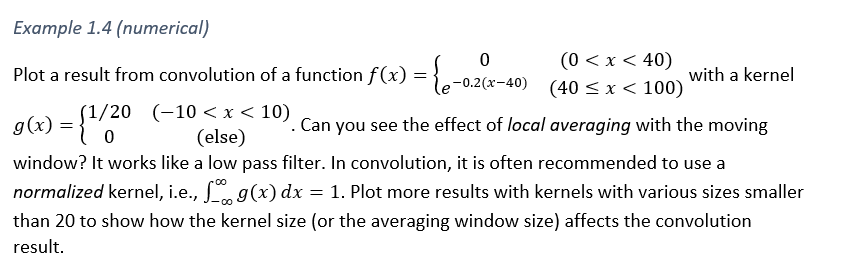

Make 1D arrays for x and f(x).

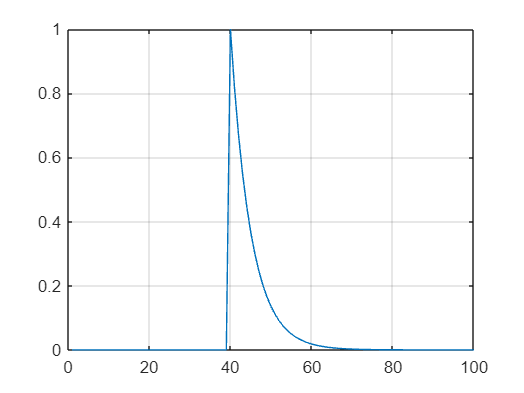

clear

x = 1:100;  % sampled x [0 100]
f = exp(-0.2*(x-40));  
f(x<40) = 0;

figure;
plot(x, f);  
xlim([0 100]);
grid on;

Make an 1D array for g(x) (kernel).

x1 = -9.5:9.5;  % x for g with the same x interval
g = ones(size(x1));
g = g/sum(g);  % normalize g 
g

g =     0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500    0.0500


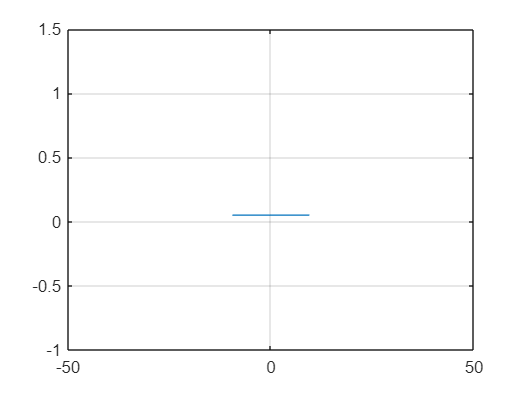


figure;
plot(x1, g);
xlim([-50 50]);
grid on;

Perform the convolution.

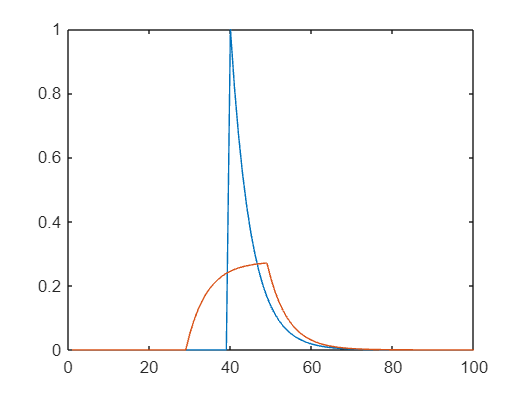

fConv = conv(f, g, 'same');

figure;
plot(x, [f', fConv']);
xlim([0 100]);

Repeat the above for various kernel sizes.

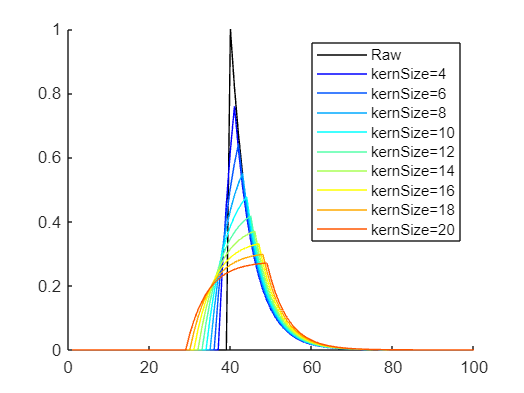

kernSize = (4:2:20);  % many kernel sizes: better to be even numbers to make g(x) symmetric
nk = length(kernSize);

figure;
line(x, f, Color='k');  % the original f(x) in black
clr = jet(nk);  % different color for different kerSize result
for ik=1:nk
    kernSize1 = kernSize(ik);

    % repeat the above for the given kernel size kernSize1
    x1 = -kernSize1/2+0.5:kernSize1/2-0.5;
    g = ones(size(x1));
    g = g/sum(g);
    
    fConv = conv(f, g, 'same');
    line(x, fConv, Color=clr(ik,:));
end
legend(cat(2, {'Raw'}, compose('kernSize=%g',kernSize)));